# week 13 

11/29    HW: kmeans, fcm, gaussian mixture model, region growing (load MRI)

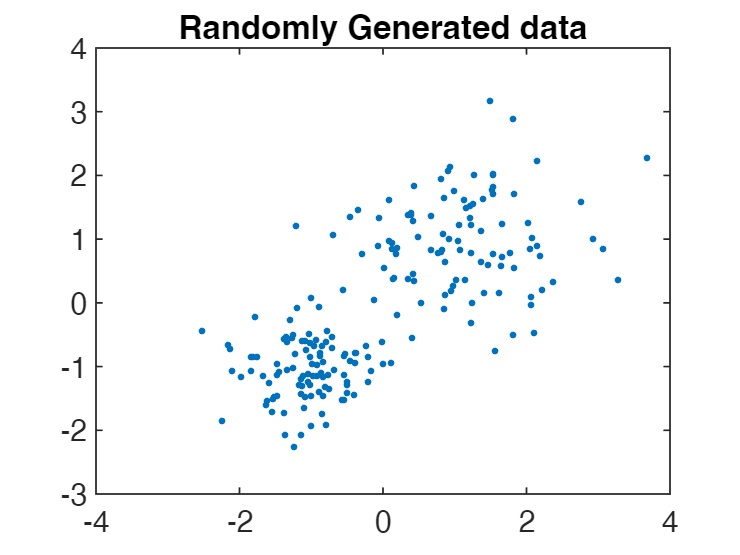

clear all;
X = [randn(100,2)*.75 + ones(100,2); randn(100,2)*0.5 - ones(100,2)];
figure; plot(X(:,1), X(:,2),'.');
title 'Randomly Generated data';


[idx, C] = kmeans(X, 2);
x1 = find(idx==1);
x2 = find(idx==2);
disp(C);

   -1.0121   -0.9838
    1.1575    0.9958



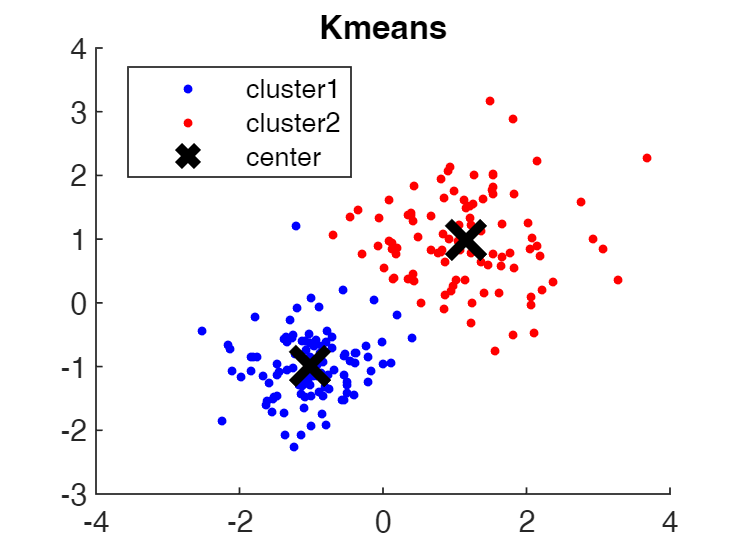

figure;
hold on;
title 'Kmeans';
plot(X(x1,1), X(x1,2),'.', ...
    'MarkerSize',8, 'Color','blue');
plot(X(x2,1), X(x2,2),'.', ...
    'MarkerSize',8, 'Color','red');
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3)
legend('cluster1', 'cluster2', 'center', 'Location', 'best');
hold off;

FCM

[centers, U] = fcm(X, 2);

Iteration count = 1, obj. fcn = 369.142342
Iteration count = 2, obj. fcn = 302.589231
Iteration count = 3, obj. fcn = 302.166636
Iteration count = 4, obj. fcn = 297.804594
Iteration count = 5, obj. fcn = 262.171284
Iteration count = 6, obj. fcn = 171.464450
Iteration count = 7, obj. fcn = 146.444761
Iteration count = 8, obj. fcn = 145.529355
Iteration count = 9, obj. fcn = 145.501996
Iteration count = 10, obj. fcn = 145.500440
Iteration count = 11, obj. fcn = 145.500315
Iteration count = 12, obj. fcn = 145.500305
Iteration count = 13, obj. fcn = 145.500304


x1 = find(U(1,:) >= 0.5);
x2 = find(U(2,:) > 0.5);
disp(centers);

    1.1885    1.0243
   -1.0021   -0.9861



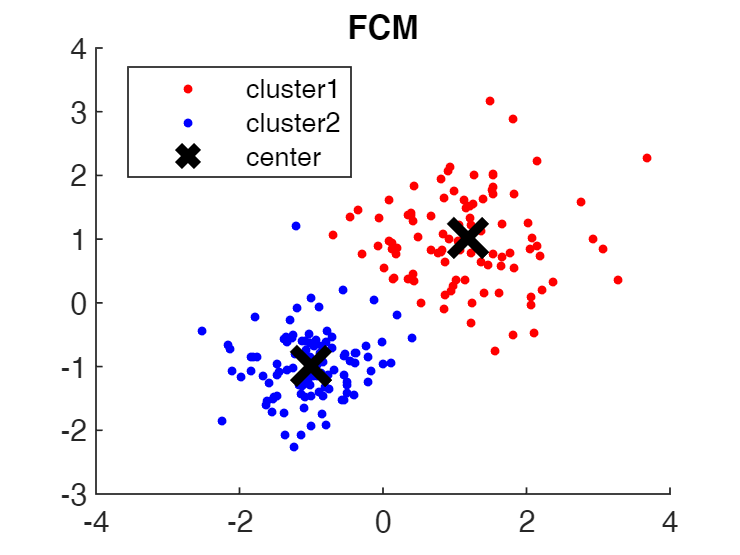

figure;
hold on;
plot(X(x1,1), X(x1,2),'.', ...
    'MarkerSize',8,'Color','red');
plot(X(x2,1), X(x2,2),'.', ...
    'MarkerSize',8,'Color','blue');
plot(centers(:,1),centers(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3)
legend('cluster1', 'cluster2', 'center', 'Location', 'best');
title 'FCM'
hold off;

gaussian mixture model

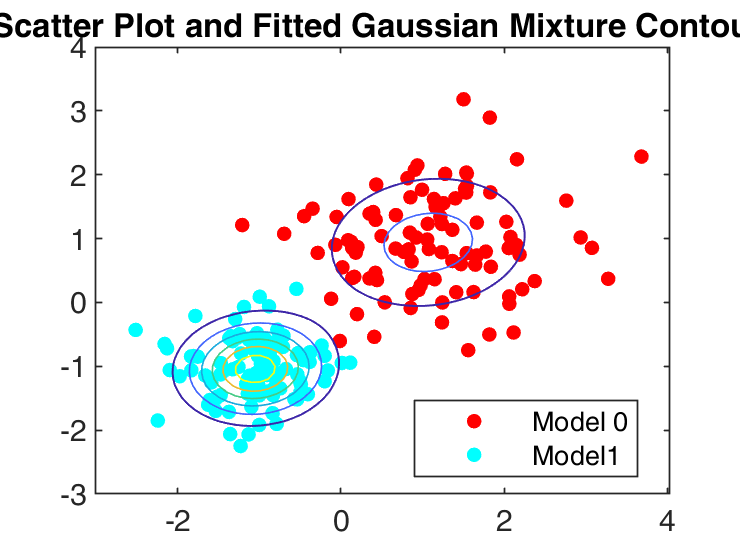

GMModel = fitgmdist(X, 2);
figure;
y = [zeros(100,1);ones(100,1)];
h = gscatter(X(:,1),X(:,2),y);
hold on;
gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(GMModel,[x0 y0]),x,y); %??
g = gca;
fcontour(gmPDF,[g.XLim g.YLim])
title('{\bf Scatter Plot and Fitted Gaussian Mixture Contours}')
legend(h,'Model 0','Model1')
hold off;

Region growing

load MRI, maybe add some noise and seperate WM and GM

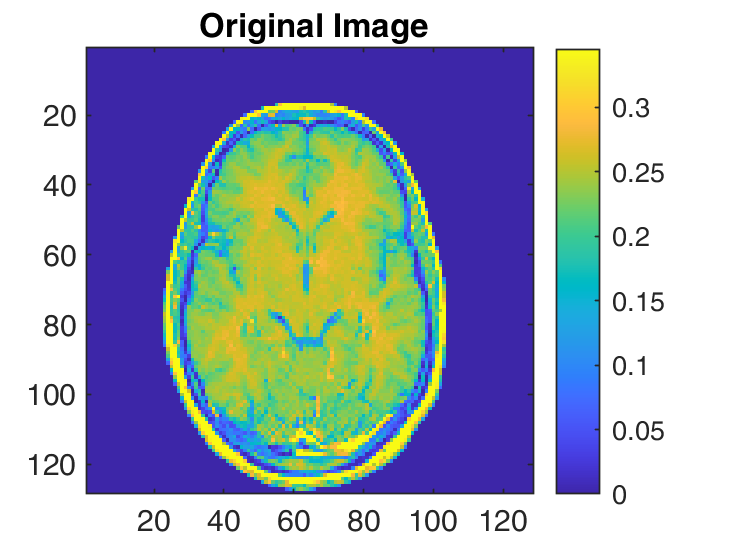

load mri.mat;
D = squeeze(D);D = im2double(D(:,:,12));
figure; imagesc(D);colorbar;axis square;
title('{\bf Original Image}');

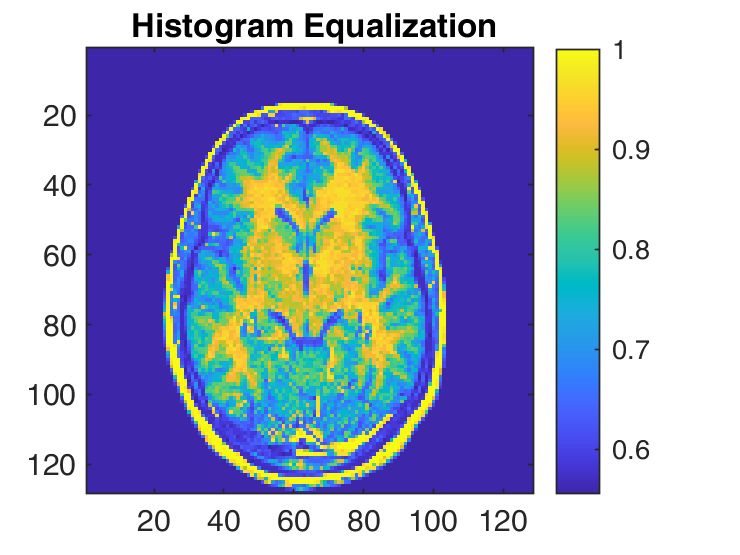

D = histeq(D);
figure; imagesc(D);colorbar;axis square;
title('{\bf Histogram Equalization}');

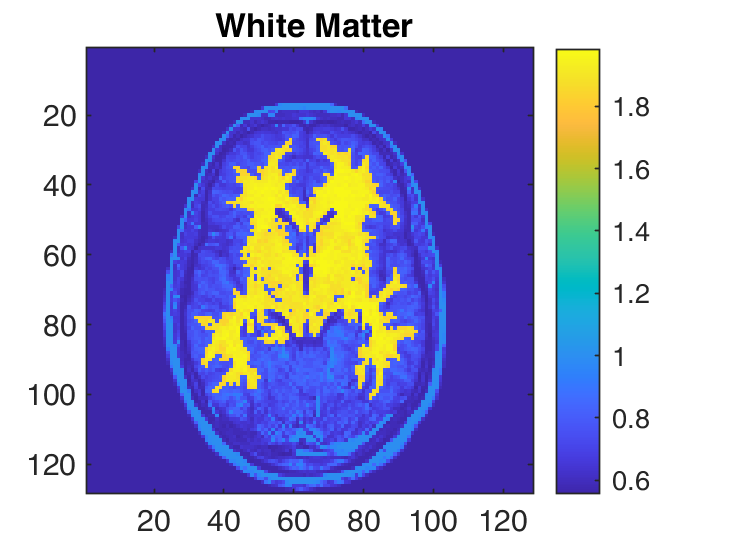


% region growing
% WM
x = 44;y = 76;
wm = regiongrowing(D, x, y, 0.08);
figure; imagesc(D+wm);colorbar;axis square;
title('{\bf White Matter}');

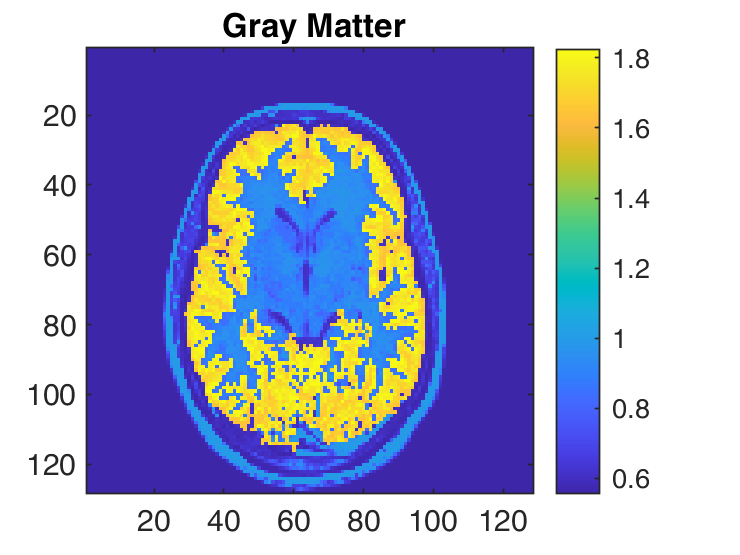

% GM
x = 42;y = 87;
gm = regiongrowing(D, x, y, 0.1);
figure; imagesc(D+gm);colorbar;axis square;
title('{\bf Gray Matter}');